# Esame CALCOLO NUMERICO 20/07/2023

## Esercizi

### 1

- Impostare sul foglio il sistema lineare che occorre risolvere per ricavare la retta ai minimi quadrati associata a un insieme di $n$ punti di coordinate $x_i$,$y_i$ con $i=1\ldotp \ldotp n$.

La retta dei minimi quadrati è una retta $y=\textrm{mx}+q$ dove


$$m=\frac{n\sum x_i y_i -\sum x_i \sum y_i }{n\sum x_i^2 -{\sum x_i }^2 }\;\;\;\;\;\;\;\;q=\frac{\sum y_i \sum x_i^2 -\sum x_i \sum x_i y_i }{n\sum x_i^2 -{\sum x_i }^2 }$$


e $x$ un vettore generato tra il valore massimo e minimo dei punti. Una retta di questo tipo può anche essere ottenuta usando i comandi `polyfit` e `polyval`.

- Implementare al calcolatore il polinomio interpolatore, evidenziando i punti di interpolazione $P_1 =\left(-2,-2\right),\;P_2 =\left(-5,\sqrt{2}\right),\;P_3 =\left(0,7\right),\;P_4 =\left(0\ldotp 1,7\right),\;P_5 =\left(\pi ,7\right)$

- Fare il grafico del polinomio interpolatore, evidenziando i punti di interpolazione.

- Sullo stesso grafico, inserire il grafico della retta ai minimi quadrati associata ai 5 punti.

- Inserire la legenda.

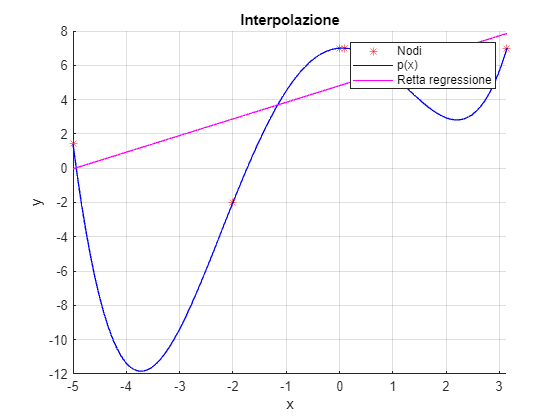

xi = [-2 -5 0 0.1 pi]; % x dei punti
yi = [-2 sqrt(2) 7 7 7]; % y dei punti
x = linspace(min(xi), max(xi), 100);
n = length(xi);

figure; hold on; grid on;
xlabel('x'); ylabel('y');
xlim([min(x) max(x)])
title('Interpolazione')
plot(xi, yi, 'r*', 'DisplayName', 'Nodi')

% Polinomio interpolatore
p = polyfit(xi, yi, n-1);
y = polyval(p, x);

plot(x, y, 'b-', 'DisplayName', 'p(x)')

% Retta di regressione
den = n*sum(xi.^2) - sum(xi)^2; % Denominatore comune
m = (n*sum(xi.*yi) - sum(xi)*sum(yi)) / den; % Coefficiente angolare
q = (sum(yi)*sum(xi.^2)-sum(xi)*sum(xi.*yi)) / den; % Punto intersezione
y = m*x + q;

plot(x, y, 'm-', 'DisplayName', 'Retta regressione')
legend

### 2

- Definire la norma infinito, sia vettoriale che matriciale.

La norma infinito vettoriale è definita come il più grande elemento del valore assoluto del vettore $v$


$$||\mathrm{v}||_{\infty } =|\max \left(\mathrm{v}\right)|_{\infty }$$


La norma infinito matriciale è definita come la somma del massimo valore assoluto delle righe di $A$


$$||A||_{\infty } =\max_{1\le i\le m} \sum_{j=1}^n |a_{\textrm{ij}} |$$


- Definire il condizionamento di un sistema lineare.

Per sistema lineare $\textrm{Ax}=b$ con $A\in M_{n\cdot n} \left(\mathbb{R}\right)$ non singolare, $x\in \mathbb{R}$ vettore colonna delle variabili e $b\in \mathbb{R}$ vettore colonna delle costanti, il condizionamento di una matrice è definito come


$$\mathrm{cond}\left(A\right)=||A||\cdot ||A^{-1} ||$$


Ci sono due comandi MATLAB che forniscono il condizionamento di una matrice: `cond` restituisce il condizionamento di una matrice con precisione, `rcond` restituisce il reciproco del condizionamento con meno precisione, utile per le matrici di grandi dimensioni.

- Data la matrice $A=\left\lbrack \begin{array}{cc}
1-\alpha  & 1\\
-1 & -1
\end{array}\right\rbrack$ fare il grafico del condizionamento in norma infinito per $0<\alpha <10$.

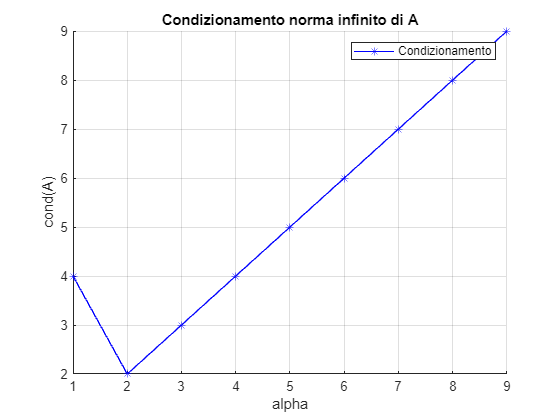

alpha = 1:9;
c = zeros(1,9);

for i = alpha(1):alpha(end)
    A = [1-i 1; -1 -1];
    c(i) = cond(A, "inf");
end

figure; hold on; grid on;
xlabel('alpha'); ylabel('cond(A)')
title('Condizionamento norma infinito di A')
plot(alpha, c, 'b*-', 'DisplayName', 'Condizionamento')
legend

- Inventare un istema lineare di cui si conosce la soluzione che abbia matrice $A$ e un termine noto opportuno.

- Risolvere in MATLAB il sistema al punto precedente e fare il grafico dell'errore commesso rispetto alla soluzione esatta al variare di $0<\alpha <10$.

Un sistema lineare $\textrm{Ax}=b$ si dice avere soluzione se il $\det \left(A\right)\not= 0$. Prendiamo la matrice $A=\left\lbrack \begin{array}{cc}
0 & 1\\
-1 & -1
\end{array}\right\rbrack$ e il vettore di termini noti $b=\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$. La soluzione esatta al sistema lineare è $x=\left\lbrack \begin{array}{c}
-1\\
1
\end{array}\right\rbrack$, verificata con l'operatore `A\b`. Le soluzioni approssimate sono calcolate al variare di $0<\alpha <10$ per la matrice $A=\left\lbrack \begin{array}{cc}
1-\alpha  & 1\\
-1 & -1
\end{array}\right\rbrack$, rispetto la soluzione esatta.

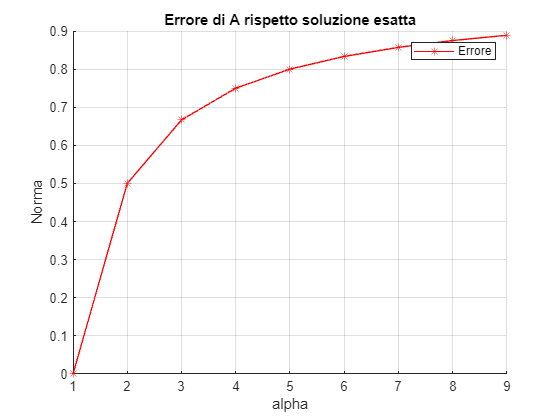

alpha = 1:9;
e = zeros(1,9);
x0 = [-1; 1];
b = [1; 0];

for i = alpha(1):alpha(end)
    A = [1-i 1; -1 -1];
    x = A\b; % Soluzione approssimata
    e(i) = norm(x0 - x, "inf");
end

figure; hold on; grid on;
xlabel('alpha'); ylabel('Norma')
title('Errore di A rispetto soluzione esatta')
plot(alpha, e, 'r*-', 'DisplayName', 'Errore')
legend

- Commentare: la matrice risulta essere bene o mal condizionata? Il condizionamento della matrice influisce sull'errore commesso sulla soluzione numerica?

La matrice $A$ al variare di $\alpha$ risulta essere mal condizionata. Notare il grafico dell'errore misurante lo scostamento rispetto la soluzione esatta. Il condizionamento è parte integrante del mptivo per cui l'errore aumenti; infatti, la definizione di condizionamento è quella di "sensibilità dell'output a piccole variazioni nell'input".